# Proměnné a jejich speciální varianty

zakladni_promenna = 5+3;

- **i**,**j**       komplexní jednotka

- **Inf**      nekonečno

- **NaN**   výsledek není číslo

- **ans   ** výsledek operace bez přiřazení

- **pi**       Ludolfovo číslo

## Vektory

v1 = [1 3 5 7 1]     % vyjmenování konkrétních hodnot

v1 =      1     3     5     7     1


v2 = 1:5             % vektor od 1 do 5 (1,2,3,4,5)

v2 =      1     2     3     4     5


v3 = 1:2:5           % vektor od 1 do 5 s krokem 2 (1,3,5)

v3 =      1     3     5


v4 = linspace(1,7,5) % vektor od 1 do 7 s 5ti prvky (lineární krok)

v4 =     1.0000    2.5000    4.0000    5.5000    7.0000


v5 = logspace(0,2,5) % vektor od 10^0 do 10^2 s 5ti prvky (logaritmický krok)

v5 =     1.0000    3.1623   10.0000   31.6228  100.0000


## Matice

A = [1 2; 3 4]              % vyjmenování konkrétních hodnot, středník = nový řádek

A =      1     2
     3     4


% u všech následujících je velikost 3x3
Jednotkova_matice = eye(3)

Jednotkova_matice =      1     0     0
     0     1     0
     0     0     1


Matice_plna_1 = ones(3)     % POZOR, nejedná se o jednotkovou matici!

Matice_plna_1 =      1     1     1
     1     1     1
     1     1     1


Matice_plna_0 = zeros(3)    % Matice plná 0

Matice_plna_0 =      0     0     0
     0     0     0
     0     0     0


Klasicka_nahodna_matice = rand(3)       % Náhodně vygenerované hodnoty mezi 0 a 1

Klasicka_nahodna_matice =     0.3500    0.6160    0.8308
    0.1966    0.4733    0.5853
    0.2511    0.3517    0.5497


Gaussovska_nahodna_matice = randn(3)    % Obsahuje rozložené hodnoty kolem 0 s gaussovským rozložením

Gaussovska_nahodna_matice =     1.5877    0.8351   -1.1658
   -0.8045   -0.2437   -1.1480
    0.6966    0.2157    0.1049



Nahodny_vektor = rand(1,6)  % 1 radek, 6 sloupcu

Nahodny_vektor =     0.7792    0.9340    0.1299    0.5688    0.4694    0.0119


## Indexace

A = rand(3);    % velikost 3x3
A(1,2)          % chci 1. řádek, 2. sloupec

ans = 0.3112

A(2,:)          % chci 2. řádek, všechny sloupce

ans =     0.1622    0.5285    0.2630


A(:,end)        % chci všechny řádky, poslední sloupec

ans =     0.6020
    0.2630
    0.6541


A(:,end) = []   % smaž poslední sloupec

A =     0.3371    0.3112
    0.1622    0.5285
    0.7943    0.1656


## Spojování matic a vektorů

radek = [1 2 3]

radek =      1     2     3


sloupec = radek'

sloupec =      1
     2
     3


A = rand(3)

A =     0.6892    0.0838    0.1524
    0.7482    0.2290    0.8258
    0.4505    0.9133    0.5383



pod_sebe = [A; radek]

pod_sebe =     0.6892    0.0838    0.1524
    0.7482    0.2290    0.8258
    0.4505    0.9133    0.5383
    1.0000    2.0000    3.0000


vedle_sebe = [A, sloupec]

vedle_sebe =     0.6892    0.0838    0.1524    1.0000
    0.7482    0.2290    0.8258    2.0000
    0.4505    0.9133    0.5383    3.0000


% [A, radek] <--- Nelze! Mám matici 3x3 a vedle toho nemám jak nalepit řádek
% [A; sloupec] <--- Nelze! Mám matici 3x3 a pod to nemám jak nalepit sloupec

## Počítání s maticemi

#### Maticové operace

Každá operace má svá pravidla. Viz předmět Matematika 1. Pozor, tyto operace nejsou komutativní.

A = [1 2; 3 4];
B = [5 6; 7 8];
radek = [1 2 3];
sloupec = [1;2;3];

A + B

ans =      6     8
    10    12


A - B

ans =     -4    -4
    -4    -4


A * B

ans =     19    22
    43    50


A / B

ans =     3.0000   -2.0000
    2.0000   -1.0000


A \ B

ans =     -3    -4
     4     5


A ^ 2  % stejné jako A*A

ans =      7    10
    15    22



radek * sloupec

ans = 14

sloupec * radek  % radek * radek nelze (špatné rozměry)

ans =      1     2     3
     2     4     6
     3     6     9


                 % nejde tedy ani radek ^ 2

#### Nematicové operace ("*tečkové operace*", "*operace prvek po prvku*")

Každý prvek se vynásobí/vydělí/.. s prvkem na stejné pozici.

A = [1 2; 3 4];
B = [5 6; 7 8];
radek = [1 2 3];
sloupec = [1;2;3];

A + B

ans =      6     8
    10    12


A - B

ans =     -4    -4
    -4    -4


A .* B

ans =      5    12
    21    32


A ./ B

ans =     0.2000    0.3333
    0.4286    0.5000


A .\ B;
A .^ B;
A .^ 2;  % stejné jako A .* A

radek .* sloupec

ans =      1     2     3
     2     4     6
     3     6     9


sloupec .* radek

ans =      1     2     3
     2     4     6
     3     6     9


radek .* radek

ans =      1     4     9


sloupec .* sloupec

ans =      1
     4
     9


radek .^ 2  % s tečkou není problém - každý prvek se umocní na 2.

ans =      1     4     9


# Užitečné funkce

## Velikost proměnné

vektor = linspace(1,5,200);
matice = rand(3,8);

delka = length(vektor) % vraci jendo cislo (delka)

delka = 200

[radku, sloupcu] = size(matice) % vraci dve cisla

radku = 3

sloupcu = 8

whos matice    % část "Bytes" říká, kolik paměti prom. zabírá

  Name        Size            Bytes  Class     Attributes

  matice      3x8               192  double              



## Zaokrouhlování

nahodna_matice = rand(3).*10

nahodna_matice =     6.2206    4.0181    1.2332
    3.5095    0.7597    1.8391
    5.1325    2.3992    2.3995


floor(nahodna_matice)   % zaokrouhlení dolů

ans =      6     4     1
     3     0     1
     5     2     2


round(nahodna_matice)   % klasické zaokrouhlení

ans =      6     4     1
     4     1     2
     5     2     2


ceil(nahodna_matice)    % zaokrouhlení nahorů

ans =      7     5     2
     4     1     2
     6     3     3


## Uživatelský vstup

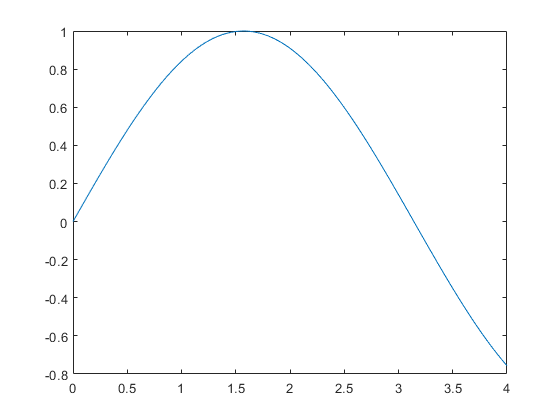

% Příklad na vykreslení funkce sinus mezi zadanými mezemi
od = input('Odkud se má sinus vykreslit - ');
do = input('Kam až se má vykreslit - ');

x = linspace(od, do, 100);
y = sin(x);
plot(x,y)

## Výpis

bez_stredniku = 1+2     % na konci řádku není středník -> vypiš hodnotu

bez_stredniku = 3

disp(bez_stredniku)     % vypíše jen hodnotu

     3



fprintf('Hodnota proměnné je : %d\n', bez_stredniku)   % komplexní výpis

Hodnota proměnné je : 3


- **%d**      celé číslo

- **%f**       reálné číslo

- **%6.2f**  reálné číslo, které se vypíše vždy minimálně na šesti pozicích s dvěma desetinými místy

- **\n**        nový řádek

## Další

vektor = rand(1, 5);

prumer = mean(vektor)

prumer = 0.5611


soucet = sum(vektor)

soucet = 2.8053


[nejvyssi_hodnota, pozice_maxima] = max(vektor)

nejvyssi_hodnota = 0.9448

pozice_maxima = 4

[nejnizsi_hodnota, pozice_minima] = min(vektor)

nejnizsi_hodnota = 0.0497

pozice_minima = 2


e_na_3 = exp(3)    % V matematice odpovídá e^3

e_na_3 = 20.0855


odmocnina = sqrt(2)

odmocnina = 1.4142

# Podmínky + cykly

## if + else

Někdy chceme zareagovat v případě opaku.

if pi > 3
    disp('Ano, pi je větší než 3');
    % ...
    % ... něco spočítám
else
    disp('V MATLABu je chyba! Pi je menší nebo rovno 3.');
end

Ano, pi je větší než 3


Případně existuje ještě nepovinná část `elseif``.`

if pi > 3
    disp('Ano, pi je větší než 3');
    % ...
    % ... něco spočítám
elseif pi > 0
    disp('Sice to není větší než 3, ale je to alespoň kladné');
    % ...
    % ... něco spočítám
else
    disp('V MATLABu je chyba! Pi je menší nebo rovno 3.');
end

Ano, pi je větší než 3


Často je zapotřebí kontrolovat více podmínek zároveň a spojit je tzv. logickým operátorem.

- &&           - a - obě podmínky musí být splněny

- ||              - nebo - stačí, když je splněna jen jedna z podmínek

Typy podmínek:

- A > B       - A je větší než B

- A >= B     - A je větší nebo rovno B

- A == B     - A je stejné jako B

- **A ~= B**     - A se nerovná B         <--- pozor, v jiných jazycích je to obvykle jinak

- A < B       - A je menší než B

- A <= B     - A je menší nebo rovno B

a = input('Zadej číslo - ');
if ((a > -1) && (a < 1)) && (a ~= 0)
    disp('číslo je celkem blízko nuly, ale nula to není')
end

## for

for k=1:3      % 1:3 může být jakykoliv vektor
    disp(k)
end

     1

     2

     3



for k=[9 1 pi]
    disp(k)
end

     9

     1

    3.1416



for k=3:-1:1   % pro obrácený chod
    disp(k)
end

     3

     2

     1



## while

k = 3;
while k > 0
    disp(k)
    k = k - 1;
end

     3

     2

     1



# Grafy

## 2D

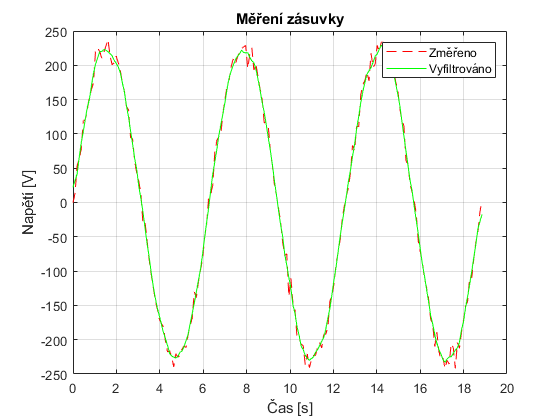

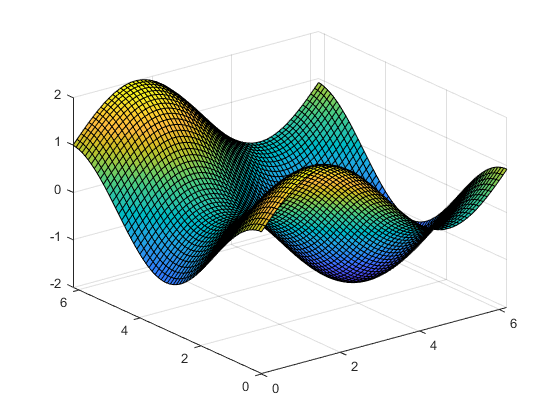

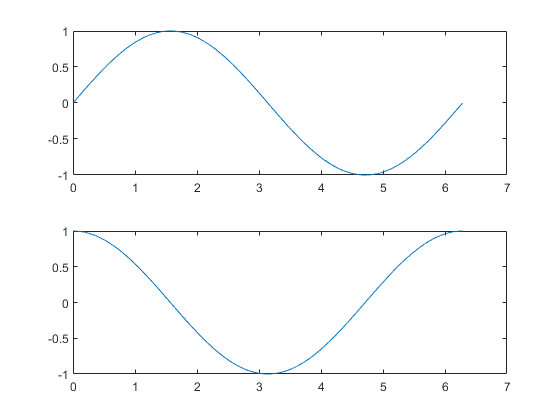

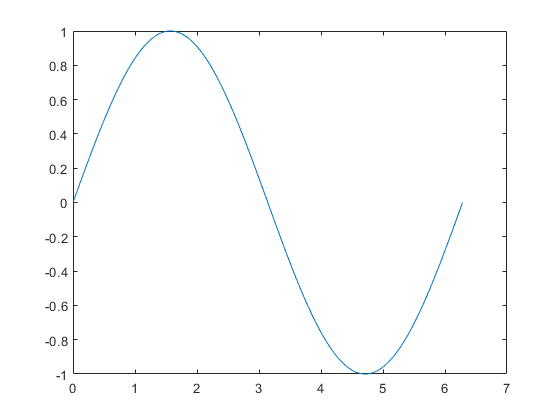

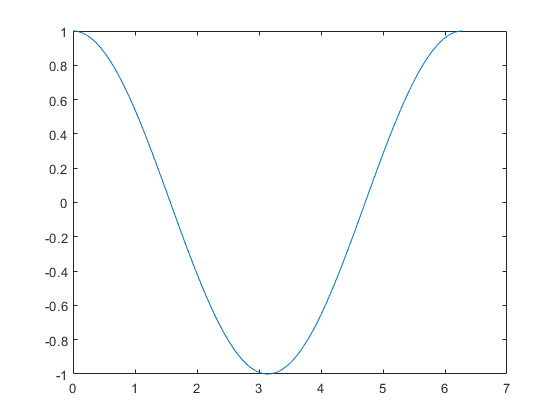

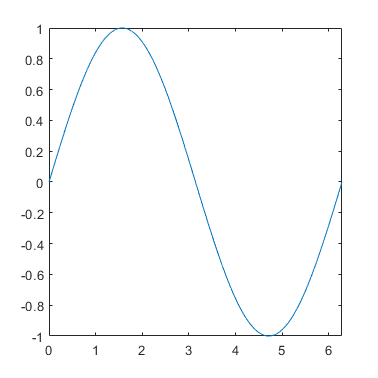

cas = linspace(0,6*pi,200);     % vektor od 0 do 6ti pi s 200 prvky
napeti = sin(cas)*230 + randn(1,200)*10;    % sinus + trochu náhody
plot(cas,napeti,'r--')          % červeně čárkovaně (více stylů v "doc plot" - LineSpec)
hold on     % počket, ještě budu něco kreslit
vyfiltrovano = movmean(napeti,5);
plot(cas,vyfiltrovano,'g')      % zelené, vyfiltrované napětí
hold off
grid on     % zapni mřížku
xlabel('Čas [s]')
ylabel('Napětí [V]')
title('Měření zásuvky')
legend('Změřeno', 'Vyfiltrováno')

#### .. uložení dat

save('mereni', 'cas','napeti','vyfiltrovano')

## 3D

figure()    % otevři mi na kreslení nové okno

data =     0.6079    0.0181    1.7742    0.4700    0.7546    0.9184    0.6307    0.0620    0.2242    0.3425    1.0946   -0.1218    0.6577    0.3797    0.0717   -0.3733   -0.0171    0.0547   -0.6603    0.1501   -0.3743   -0.0242    0.1805   -0.4473   -0.1432    0.1751   -0.9154    0.5263    1.2295    0.5092   -0.1129    0.2781   -0.4322    1.0500    0.6100    0.5652   -0.2313    0.4049    0.0075    0.1758    0.0947   -0.0818    0.0314    0.4388   -0.2445    0.9732    0.6783    1.1578    1.0173    1.2071


[X,Y] = meshgrid(0:0.1:2*pi);
Z = sin(X) + cos(Y);

p =     0.9906    0.0412   -0.0353


surf(X,Y,Z)

## Více grafů

#### ... v jednom okně

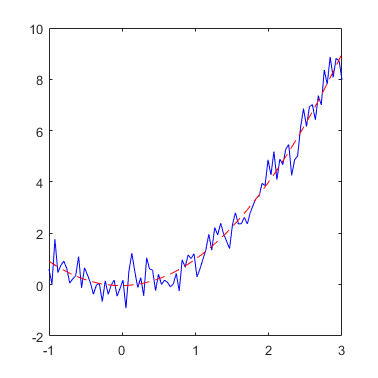

figure()    % otevři mi na kreslení nové okno
x = 0:0.001:2*pi;


subplot(2,1,1)  % 2 řádky, 1 sloupec, 1. graf
plot(x, sin(x))

subplot(2,1,2)  % 2 řádky, 1 sloupec, 2. graf
plot(x, cos(x))

#### ... ve více oknech

x = 0:0.001:2*pi;

figure(5)
plot(x, sin(x))

figure(6)
plot(x, cos(x))

## Uložení grafu (obrázku)

fig = figure(7);
x = 0:0.001:2*pi;
plot(x, sin(x))

saveas(fig, 'myPicture.png')    % obrázek

width = 10;
height = 10;
fig.Units = 'Centimeters';
fig.Position = [5, 5, width, height];
fig.PaperSize = [width, height];
saveas(fig, 'myPicture.pdf')    % vektorové

# Polynomy

x = linspace(-1,3,100);
data = x.^2 + randn(1,100).*0.5

p = polyfit(x,data, 2)  % zjisti, jak vypadá polynom, který by sedl na ty data
                        % stupeň polynomu 2 ... a*x^2 + b*x + c
data_polynomu = polyval(p, x);
plot(x,data,'b', x, data_polynomu,'r--')